Prof. Dr. Ralf Hielscher 

Erik Wünsche

TU Bergakademie Freiberg

Summer Semester 2025

# Mathematical Image Processing - Exercise Sheet 4

Download the zip file` Sheet4.zip `with the images for the following tasks from OPAL. Please make sure your current working directory (Working directory/Current Folder) in MATLAB matches the folder where the exercises are located.

**Important Tips:**

- Use **Ctrl+Enter** to run a section.

- Use **Ctrl+Alt+Enter** to insert section breaks.

- Use **F9** to execute highlighted code in the command window.

### Exercise 1: (Image Registration)

In this exercise there are given 2 images of the same object. The input images differs by some rotation, scale and translation. Your task is  to calculate the rotation angle, the scale factor and the x- and y- shift parameters.

Therefore we load the image` butterfly.png `and use the function

`  [u,v] = defaultImages(img,angle,scale,[xshift,yshift])`

to create an image` u `and an manipulated image` v`.

#### (i) Translation

At first we assume there is only translation (no scale, no rotation).

Lets construct 2 images.

clear

xshift = -200;
yshift = 80;
degree = pi/180;

% Construct image
img = double(rgb2gray(imread('butterfly.png')))/255;
[u,v] = defaultImages(img,0*degree,1,[xshift,yshift]);

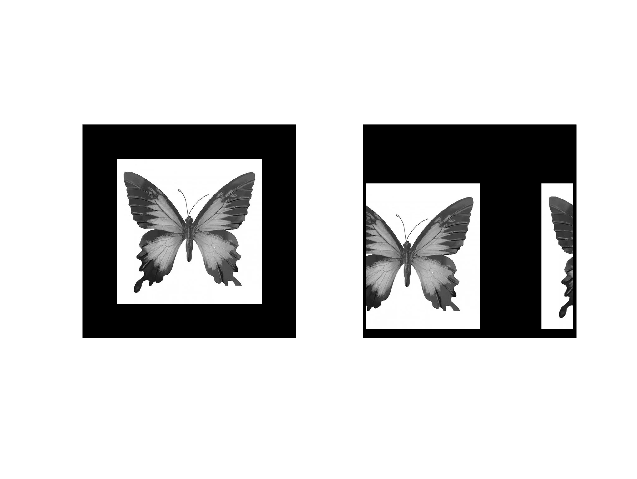

% plot initial images
figure
subplot(1,2,1)
IM = padarray(u,[10 10],0,'both');
imshow(IM)
subplot(1,2,2)
IM = padarray(v,[10 10],0,'both');
imshow(IM)

The given images satisfy

            $v_{k,l} = u_{k+x_0\,,\,l+y_0}$.

Now we compute the translation by computing the normalized cross power spectrum / phase correlation (PC), i.e.

              $PC_{m,n} = \frac{[\hat u \, \cdot \,\overline{\hat v}]_{m,n}}{|\hat u_{m,n}|\,|\hat v_{m,n}|} = \mathrm{e}^{\frac{2\pi\mathrm{i}(km+ln)}N}$.

Then the inverse FFT of $PC$ yields the matrix

              $\mathrm F^*_N \, PC = \delta_{m,n}$.

% Compute translation
% IDE
% normalized cross power spectrum / phase correlation (PC)
Fu = fft2(u);
Fv = fft2(v);
PC = (Fu.*conj(Fv))./abs(Fu.*Fu);
% max of phase of PC
c = ifftshift(ifft2((PC)));
m = max(abs(c(:)));
[rows,cols] = find(abs(c)>m*(1-eps));
% shift rows and cols to get translation
x0 = -(cols-(width(u)-1)/2-2);
y0 = rows-(height(u)-1)/2-2;
shift = [x0,y0]

shift =   -200   -80


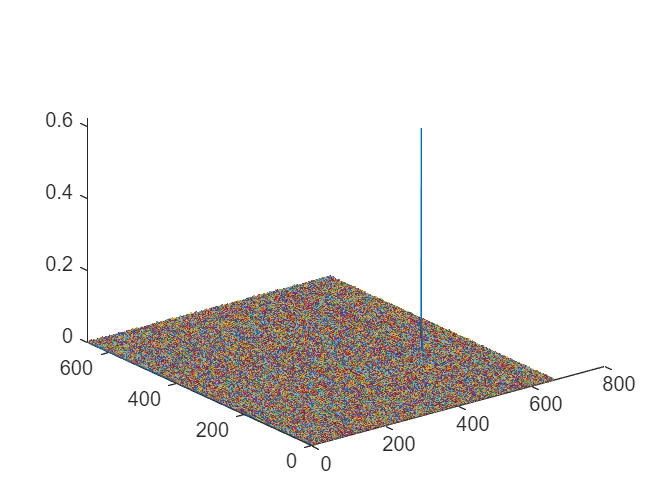

[x,y] = meshgrid(1:size(c,1));
figure
plot3(x,y,abs(c))

#### (ii) Rotation

Lets assume there is only rotation (no scale, no translation).

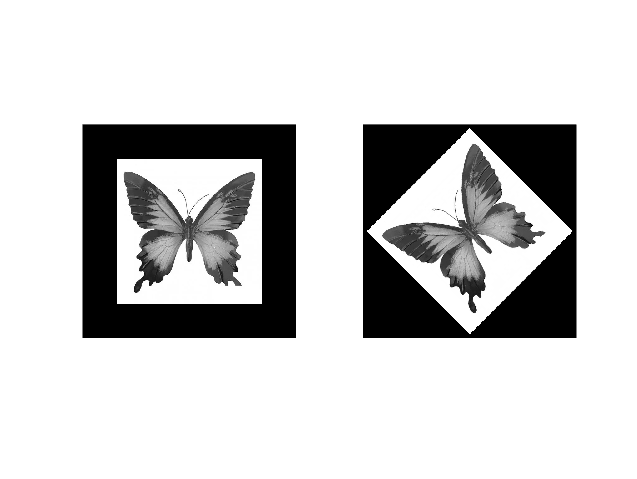

clear

degree = pi/180;
rotangle = 45*degree;

% Construct image
img = double(rgb2gray(imread('butterfly.png')))/255;
[u,v] = defaultImages(img,rotangle,1,[0,0]);

% plot initial images
figure
subplot(1,2,1)
IM = padarray(u,[10 10],0,'both');
imshow(IM)
subplot(1,2,2)
IM = padarray(v,[10 10],0,'both');
imshow(IM)

Lets take a look on the 2-dim continuous setting, i.e. let $v(\vec x) = u(R_\omega \vec x)$, where $R_\omega = \left(\begin{array}{cc} \cos \omega & \sin\omega \\ -\sin\omega & \cos\omega \end{array}\right)$ denotes the rotation with angle $\omega\in[0,2\pi)$. By Fourier rotation theorem holds $\mathcal F ( u ( R_\omega \cdot ) ) (\vec\xi)  = \mathcal F u(R_\omega \vec\xi)$. Hence, the Fourier transform satisfies $\hat v(\vec \xi) = \hat u (R_\omega \vec \xi)$ in cartesian coordinates.

The trick is to use polar coordinates, i.e. $\tilde \hat v(t,\psi) = \hat v(t\cos\psi,t\sin\psi)$.

Then the rotation with angle $\omega$ simply reads as shift, i.e.

          
$$\tilde \hat v(t,\psi) = \tilde \hat u(t,\psi+\omega)$$


and can be determined with the same methods as before, by searching the tranlation of $\tilde\hat u$ and $\tilde \hat v$.

% Fourier-Transform
Fu = fftshift(fft2(ifftshift(u)));
Fv = fftshift(fft2(ifftshift(v)));

% Interpolate on Polar grid
% We know the function values of Fu & Fv on an equispaced grid [X,Y] \in [-pi,pi]^2
[X,Y] = meshgrid((0:length(u)-1)/length(u)*2*pi-pi,(0:length(u)-1)/length(u)*2*pi-pi);
% We interpolate on an equispaced polar coordinate grid (R,phi) by transforming this to [Xpolar,Ypolar].
% Hence PolarFu & PolarFv is Fu,Fv evaluated at the polar coordinate grid (R,phi).
% Let r is in (0,pi]
r = (0.5:0.5:180)*degree;
phi = (0:359)*degree;
[R,Phi] = meshgrid(r,phi);
Xpolar = R.*cos(Phi);
Ypolar = R.*sin(Phi);
FuPolar = interp2(X,Y,Fu,Xpolar,Ypolar,'spline');
FvPolar = interp2(X,Y,Fv,Xpolar,Ypolar,'spline');

% Compute rotational angle and scale factor 
% normalized cross power spectrum / phase correlation (PC)
F1 = fft2(FuPolar);
F2 = fft2(FvPolar);
PC = (F1.*conj(F2))./abs(F1.*F2);
% max of phase of PC
c = ifft2(PC);
m = max(abs(c(:)));
[rows,~] = find(abs(c)>=m-eps);

computed_angle = phi(rows)/degree

computed_angle = 45

rows

rows = 46

#### (iii) Rotation + Scale

Lets assume there is rotation and scale (no translation).

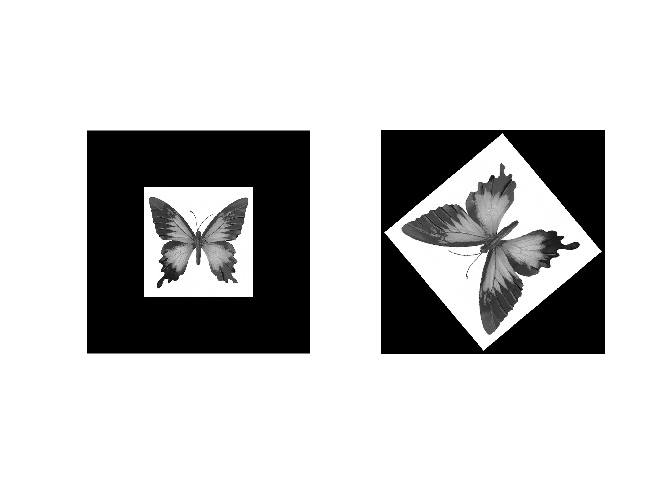

clear

degree = pi/180;
rotangle = 130*degree;
scale = 1.4;  % should be in [0.3 , pi]

% Construct image
img = double(rgb2gray(imread('butterfly.png')))/255;
[u,v] = defaultImages(img,rotangle,scale,[0,0]);

% plot initial images
figure
subplot(1,2,1)
IM = padarray(u,[10 10],0,'both');
imshow(IM)
subplot(1,2,2)
IM = padarray(v,[10 10],0,'both');
imshow(IM)

The idea is nearly the same as before:

Lets take a look on the 2-dim continuous setting, i.e. let $v\Big(\vec x\Big) = u\Big( \alpha \cdot R_\omega \vec x\Big)$, where $R_\omega = \left(\begin{array}{cc} \cos \omega & \sin\omega \\ -\sin\omega & \cos\omega \end{array}\right)$ denotes the rotation with angle $\omega\in[0,2\pi)$. and $\alpha>0$ is the scale factor. 

For linear mappings $A$ holds $\mathcal F ( u ( A \cdot ) ) (\vec\xi)  = \frac{1}{\mathrm{det} A} \mathcal F u(A \vec\xi)$. Hence, the Fourier transform satisfies $\hat v(\vec \xi) = \frac1{\mathrm{det} A} \hat u (A^{-T} \vec \xi)$ in cartesian coordinates. In our setting $A = \alpha  \cdot R_\omega$, $A^{-T} = \frac1{\alpha} \cdot R_\omega$ and $\mathrm{det}A = \frac1{\alpha^2}$.

Now we use logarithmic polar coordinates, i.e. $\Phi\colon\mathbb R \times [0,2\pi) \to \mathbb R^2$ with $\Phi(\rho,\psi) = \left( \begin{array}{cc} \mathrm e^\rho \cdot \cos\psi \\ \mathrm e^\rho \cdot \sin\psi\end{array} \right)$.

we obtain $\tilde \hat v(\rho,\psi) = \frac1{\alpha^2} \cdot \tilde \hat u(\rho - \log \alpha,\psi+\omega)$.

Hence, $\log\alpha$ and $\omega$ can be determined with the same methods as before, by searching the tranlation of $\tilde\hat u$ and $\tilde \hat v$ with the PC.

Why can the pre-factor $\frac1{\alpha^2}$ be ignored within the PC computation?

% Fourier-Transform
Fu = fftshift(fft2(ifftshift(u)));
Fv = fftshift(fft2(ifftshift(v)));

% Interpolate on Polar grid
% We know the function values of Fu & Fv on an equispaced grid [X,Y] \in [-pi,pi]^2
[X,Y] = meshgrid((0:length(u)-1)/length(u)*2*pi-pi,(0:length(u)-1)/length(u)*2*pi-pi);
% We interpolate on an equispaced polar coordinate grid (R,phi) by transforming this to [Xpolar,Ypolar].
% Hence PolarFu & PolarFv is Fu,Fv evaluated at the polar coordinate grid (R,phi).
% Let r is in (0,pi]
r = exp((-180:180)/180*log(pi));
phi = (0:359)*degree;
[R,Phi] = meshgrid(r,phi);
Xpolar = R.*cos(Phi);
Ypolar = R.*sin(Phi);
FuPolar = interp2(X,Y,Fu,Xpolar,Ypolar,'spline');
FvPolar = interp2(X,Y,Fv,Xpolar,Ypolar,'spline');


% Compute rotational angle and scale factor 
% normalized cross power spectrum / phase correlation (PC)
F1 = fft2(FuPolar);
F2 = fft2(FvPolar);
PC = (F1.*conj(F2))./abs(F1.*F2);
% max of phase of PC
c = ifft2(PC);
m = max(abs(c(:)));
[rows,cols] = find(abs(c)>=m-eps);
computed_angle = phi(rows)/degree

computed_angle = 40

computed_scale = r(mod(cols+180,length(r)))

computed_scale = 1.4008

#### (iv) Rotation + Scale + Translation)

Lets assume all together.

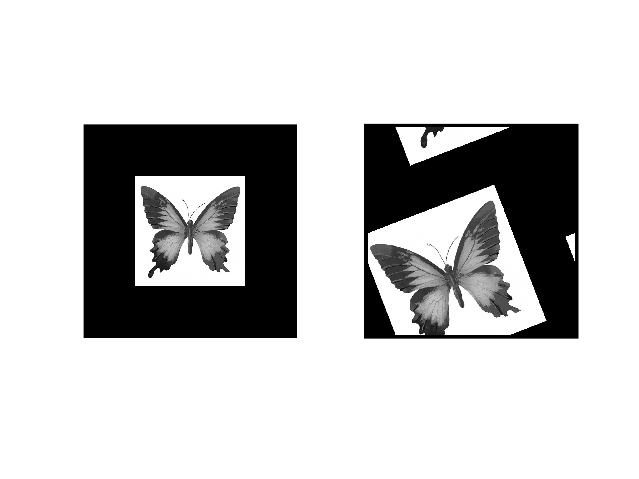

clear
degree = pi/180;
rotangle = 21*degree;
scale = 1.315;  % should be in [0.3 , pi]
shift = [-80,200];

% Construct default images
%img = double(imread('lena.png'))/255;
img = double(rgb2gray(imread('butterfly.png')))/255;
[u,v] = defaultImages(img,rotangle,scale,shift);

% Add noise
% v = imnoise(v,"gaussian",0,0.1);
% v = imnoise(v,'salt & pepper',0.3);

% plot inital images
figure
subplot(1,2,1)
IM = padarray(u,[15 15],0,'both');
imshow(IM)
subplot(1,2,2)
IM = padarray(v,[15 15],0,'both');
imshow(IM)

Putting all together, we have

            $v\Big(\vec x\Big) = u\Big(\alpha\cdot R_\omega \vec x + \vec t\Big)$.

Then the Fourier transform reads as

            
$$\hat v \Big( \vec \xi\Big) = \frac1{\alpha^2} \, \hat u\Big( \frac1{\alpha} R_\omega \vec \xi \Big) \, \mathrm e^{-2\pi\mathrm i \frac1\alpha \vec t \cdot R_\omega \vec \xi}$$


The translation effects only the phase of the Fourier transform. Hence we do 2 steps:

- Compute the rotational angle $\omega$ and the scaling factor $\alpha$ with the PC of $|\hat u|$ and $|\hat v|$ in log polar coordinates.

- Scale and rotate the initial image $u$, such that $w\Big(\vec x\Big) := u\Big( \alpha \cdot R_\omega \vec x\Big)$.

- Compute the translation $\vec t$ by PC of $v$ and $w$.

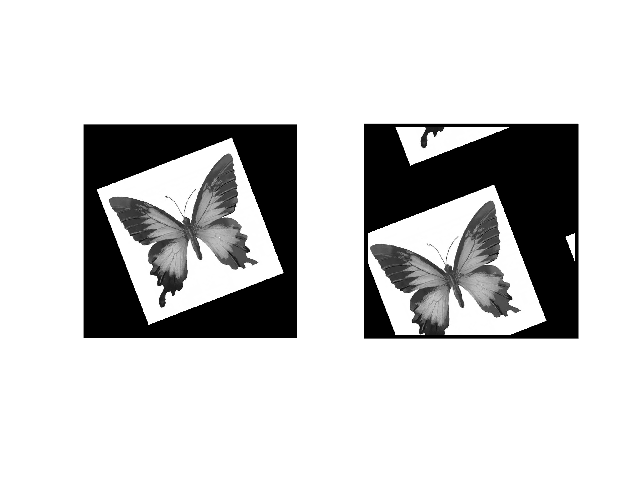

% Fourier-Transform
Fu = fftshift(fft2(ifftshift(u)));
Fv = fftshift(fft2(ifftshift(v)));

% Interpolate on Polar grid
% We know the function values of Fu & Fv on an equispaced grid [X,Y] \in [-pi,pi]^2
[X,Y] = meshgrid((0:length(u)-1)/length(u)*2*pi-pi,(0:length(u)-1)/length(u)*2*pi-pi);
% We interpolate on an equispaced polar coordinate grid (R,phi) by transforming this to [Xpolar,Ypolar].
% Hence PolarFu & PolarFv is Fu,Fv evaluated at the polar coordinate grid (R,phi).
% Let r is in (0,pi]
r = exp((-180:180)/180*log(pi));
phi = (0:359)*degree;
[R,Phi] = meshgrid(r,phi);
Xpolar = R.*cos(Phi);
Ypolar = R.*sin(Phi);
FuPolar = interp2(X,Y,abs(Fu),Xpolar,Ypolar,'spline');
FvPolar = interp2(X,Y,abs(Fv),Xpolar,Ypolar,'spline');


% Compute rotational angle and scale factor 
% normalized cross power spectrum / phase correlation (PC)
F1 = fft2(FuPolar);
F2 = fft2(FvPolar);
PC = (F1.*conj(F2))./abs(F1.*F2);
% max of phase of PC
c = ifft2(PC);
m = max(abs(c(:)));
[rows,cols] = find(abs(c)>=m-eps);
computed_angle = phi(rows)/degree;
computed_scale = r(mod(cols+180,length(r)));

% Compute translation

% rotate and scale u
w = 1-imrotate(1-u,computed_angle,'crop');
szN = round((computed_scale*size(w))/2)*2+1;
w = imresize(w,szN);
% make v,w of same pixel size
cut = centerCropWindow2d(size(w),size(v));
w = imcrop(w,cut);

% plot both images
figure
subplot(1,2,1)
IM = padarray(w,[15 15],0,'both');
imshow(IM)
subplot(1,2,2)
IM = padarray(v,[15 15],0,'both');
imshow(IM)


% Compute shift
Fw = fftshift(fft2(ifftshift(w)));
PC = (Fw.*conj(Fv))./abs(Fw.*Fv);
c = ifftshift(ifft2((PC)));
m = max(abs(c(:)));
[rows,cols] = find(abs(c)>m-eps);
x0 = -(cols-(length(v)-1)/2-2);
y0 = rows-(length(v)-1)/2-2;
computed_shift = [x0,y0];

% Output
computed_angle

computed_angle = 21

computed_scale

computed_scale = 1.3145

computed_shift

computed_shift =    -80  -200
